# DH Parameters

## Modified DH Parameters. 

Following the Book. Introduction to Robotics by John Craight

### Forward kinematics of a link

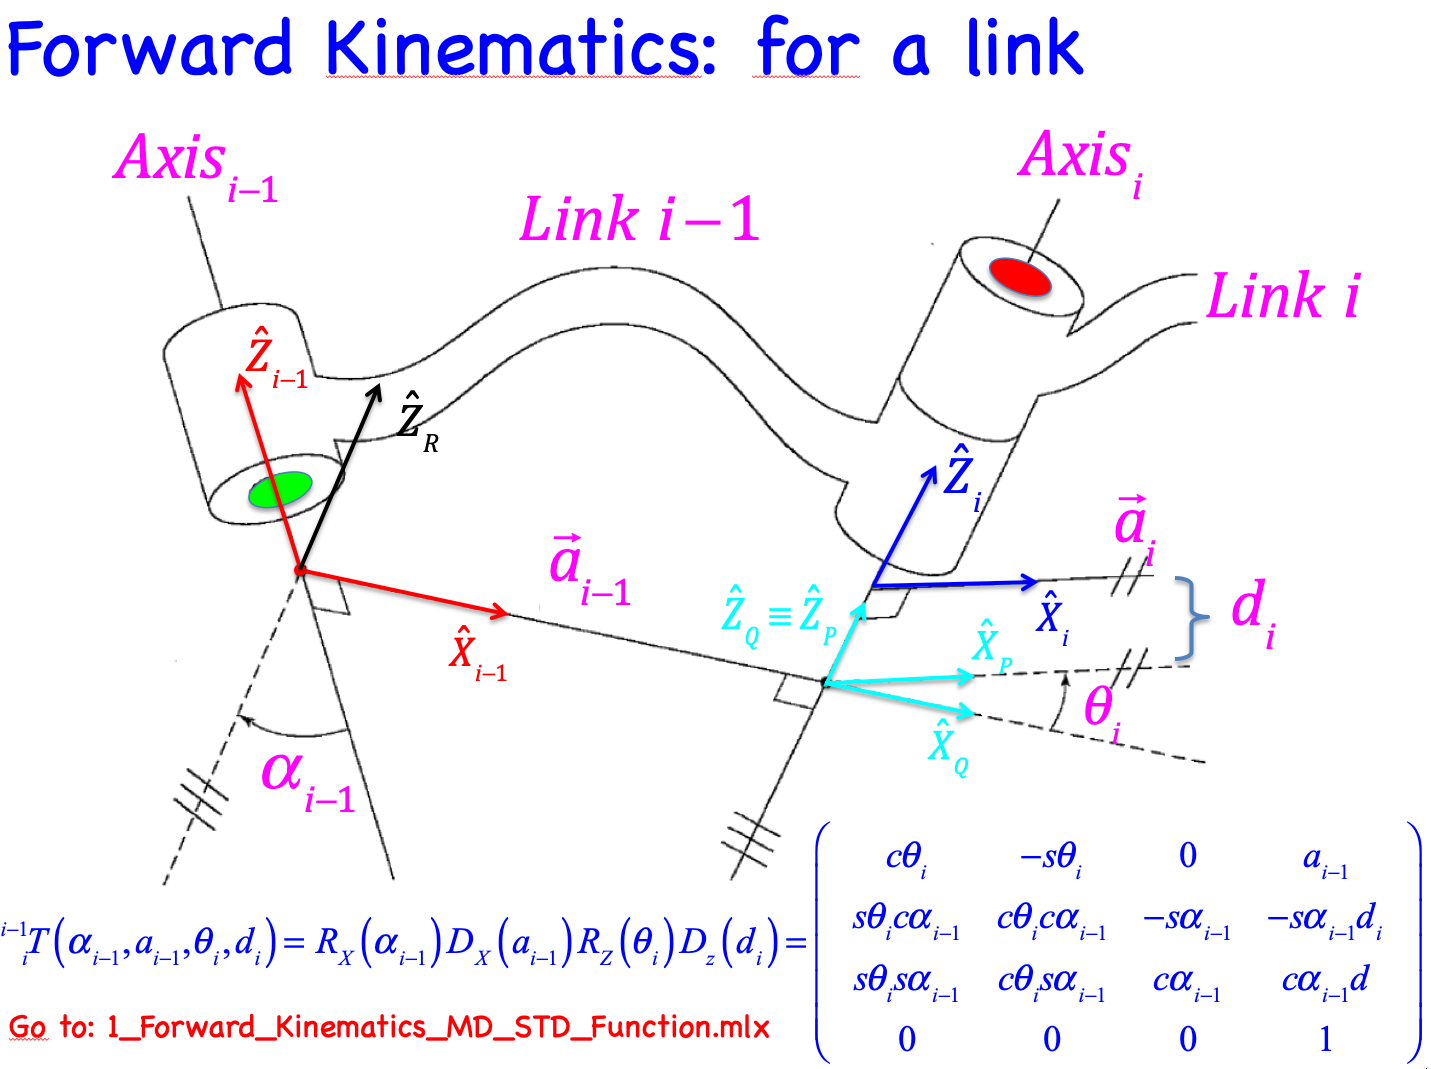

In the symbolic expresion it is used ${\alpha_{i,1} \;\textrm{in}\;\textrm{substitution}\;\textrm{of}\;\alpha }_{i-1} \;\textrm{and}\;\;{a_{i,1} \;\textrm{in}\;\textrm{substitution}\;\textrm{of}\;a}_{i-1}$

clear

As an anonimous function

T_B_A = @(alphai1,ai1,thetai,di)trotx(alphai1)*transl(ai1,0,0)*trotz(thetai)*transl(0,0,di)

T_B_A = function_handle with value:
    @(alphai1,ai1,thetai,di)trotx(alphai1)*transl(ai1,0,0)*trotz(thetai)*transl(0,0,di)


%T_b_a=T_B_A(alpha_i_1,a_i_1,theta_i,di)

syms alpha_i_1 a_i_1 theta_i  d_i
T_b_a=trotx(alpha_i_1)*transl(a_i_1,0,0)*trotz(theta_i)*transl(0,0,d_i)

$$T\_b\_a = \left(\begin{array}{cccc} \cos\left(\theta_{i}\right) & -\sin\left(\theta_{i}\right) & 0 & a_{i,1}\\ \cos\left(\alpha_{i,1}\right)\,\sin\left(\theta_{i}\right) & \cos\left(\alpha_{i,1}\right)\,\cos\left(\theta_{i}\right) & -\sin\left(\alpha_{i,1}\right) & -d_{i}\,\sin\left(\alpha_{i,1}\right)\\ \sin\left(\alpha_{i,1}\right)\,\sin\left(\theta_{i}\right) & \sin\left(\alpha_{i,1}\right)\,\cos\left(\theta_{i}\right) & \cos\left(\alpha_{i,1}\right) & d_{i}\,\cos\left(\alpha_{i,1}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_b_a=T_B_A(alpha_i_1,a_i_1,theta_i,d_i)

$$T\_b\_a = \left(\begin{array}{cccc} \cos\left(\theta_{i}\right) & -\sin\left(\theta_{i}\right) & 0 & a_{i,1}\\ \cos\left(\alpha_{i,1}\right)\,\sin\left(\theta_{i}\right) & \cos\left(\alpha_{i,1}\right)\,\cos\left(\theta_{i}\right) & -\sin\left(\alpha_{i,1}\right) & -d_{i}\,\sin\left(\alpha_{i,1}\right)\\ \sin\left(\alpha_{i,1}\right)\,\sin\left(\theta_{i}\right) & \sin\left(\alpha_{i,1}\right)\,\cos\left(\theta_{i}\right) & \cos\left(\alpha_{i,1}\right) & d_{i}\,\cos\left(\alpha_{i,1}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Chain link connection for Puma 560 Manipulator.

We solve the problem link by link symbolicaly

In fact chain link connection is equivalent to the Forward Kinematics function.

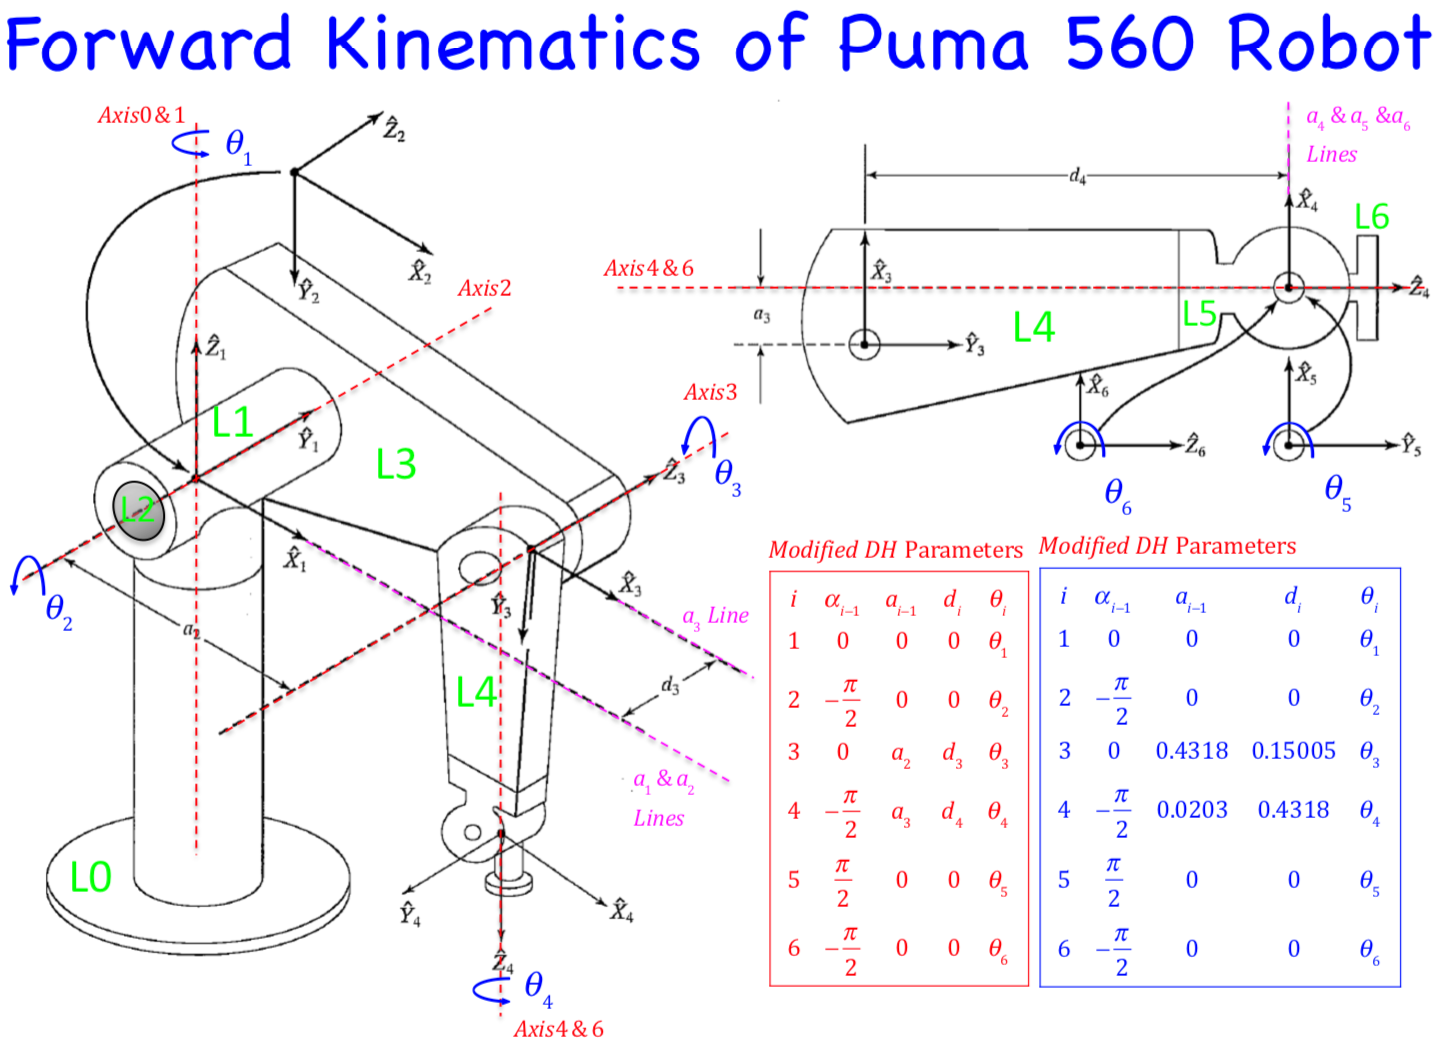

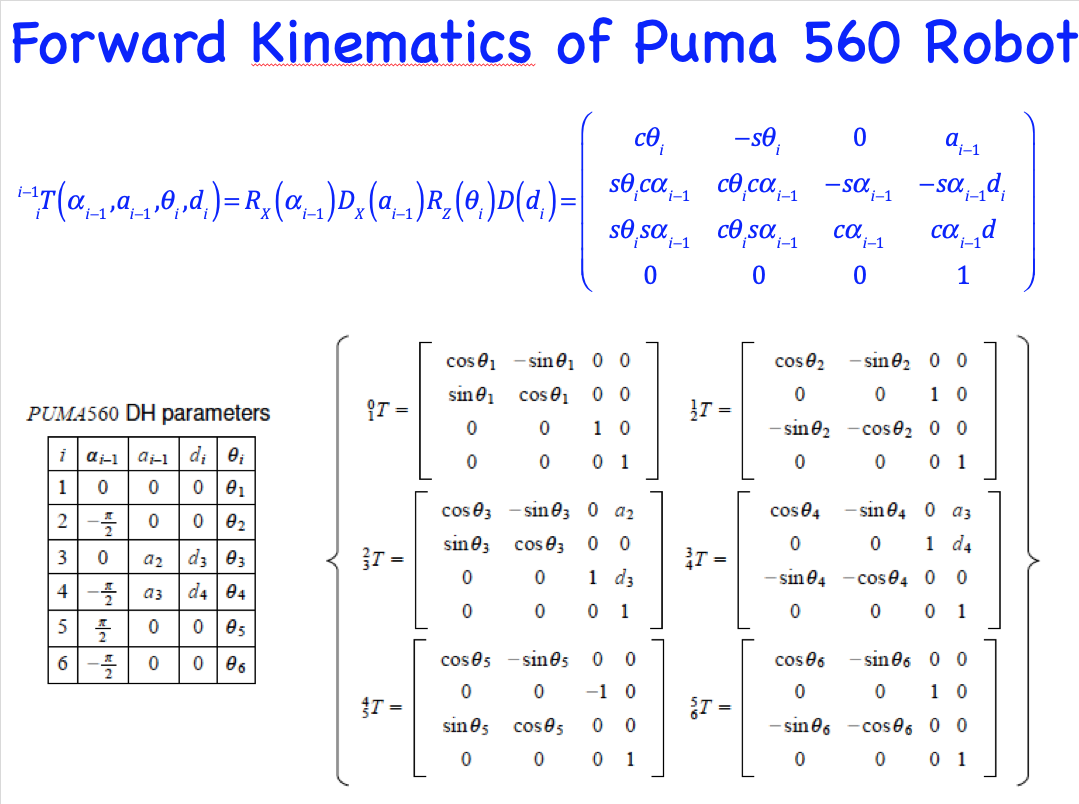

In the symbolic expresion it is used ${\alpha_{i,1} \;\textrm{in}\;\textrm{subtitution}\;\textrm{of}\;\alpha }_{i-1} \;\textrm{and}\;\;{a_{i,1} \;\textrm{in}\;\textrm{subtitution}\;\textrm{of}\;a}_{i-1}$   

T1_0=T_B_A(0,0,theta_i,0)

$$T1\_0 = \left(\begin{array}{cccc} \cos\left(\theta_{i}\right) & -\sin\left(\theta_{i}\right) & 0 & 0\\ \sin\left(\theta_{i}\right) & \cos\left(\theta_{i}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T2_1=T_B_A(-pi/2, 0, theta_i, 0)

$$T2\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{i}\right) & -\sin\left(\theta_{i}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ -\sin\left(\theta_{i}\right) & -\cos\left(\theta_{i}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T3_2=T_B_A(0, a_i_1, theta_i, d_i)

$$T3\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{i}\right) & -\sin\left(\theta_{i}\right) & 0 & a_{i,1}\\ \sin\left(\theta_{i}\right) & \cos\left(\theta_{i}\right) & 0 & 0\\ 0 & 0 & 1 & d_{i}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T4_3=T_B_A(-pi/2, a_i_1, theta_i, d_i)

$$T4\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{i}\right) & -\sin\left(\theta_{i}\right) & 0 & a_{i,1}\\ 0 & 0 & 1 & d_{i}\\ -\sin\left(\theta_{i}\right) & -\cos\left(\theta_{i}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T5_4=T_B_A(pi/2, 0,theta_i, 0)

$$T5\_4 = \left(\begin{array}{cccc} \cos\left(\theta_{i}\right) & -\sin\left(\theta_{i}\right) & 0 & 0\\ 0 & 0 & -1 & 0\\ \sin\left(\theta_{i}\right) & \cos\left(\theta_{i}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T6_5=T_B_A(-pi/2, 0, theta_i, 0)

$$T6\_5 = \left(\begin{array}{cccc} \cos\left(\theta_{i}\right) & -\sin\left(\theta_{i}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ -\sin\left(\theta_{i}\right) & -\cos\left(\theta_{i}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Fordward Kinematics by hand

We create a function for Link description: link_A_B_Md(alpha_i-1, a_i-1, d, theta.)

We test fkine_hand function putting all the qz joint vector at home, i.e. all theta = 0

T_1_0=T_B_A(0,0,0,0)

T_1_0 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


T_2_1=T_B_A(-pi/2,0,0,0)

T_2_1 =      1     0     0     0
     0     0     1     0
     0    -1     0     0
     0     0     0     1


T_3_2=T_B_A(0,0.4318,0,0.15005)

T_3_2 =     1.0000         0         0    0.4318
         0    1.0000         0         0
         0         0    1.0000    0.1500
         0         0         0    1.0000


T_4_3=T_B_A(-pi/2,0.0203,0,0.4318)

T_4_3 =     1.0000         0         0    0.0203
         0         0    1.0000    0.4318
         0   -1.0000         0         0
         0         0         0    1.0000


T_5_4=T_B_A(pi/2,0,0,0)

T_5_4 =      1     0     0     0
     0     0    -1     0
     0     1     0     0
     0     0     0     1


T_6_5=T_B_A(-pi/2,0,0,0)

T_6_5 =      1     0     0     0
     0     0     1     0
     0    -1     0     0
     0     0     0     1


T_6_0=T_1_0*T_2_1*T_3_2*T_4_3*T_5_4*T_6_5

T_6_0 =     1.0000         0         0    0.4521
         0   -1.0000         0    0.1500
         0         0   -1.0000   -0.4318
         0         0         0    1.0000


T_EE_hand_made=T_6_0

T_EE_hand_made =     1.0000         0         0    0.4521
         0   -1.0000         0    0.1500
         0         0   -1.0000   -0.4318
         0         0         0    1.0000


Position=transl(T_EE_hand_made)

Position =     0.4521
    0.1500
   -0.4318


Orientation=tr2rpy(T_EE_hand_made)

Orientation =     3.1416         0         0


T_1_0=link_A_B_Md(0,0,0,0)

T_1_0 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


T_2_1=link_A_B_Md(-pi/2,0,0,0)

T_2_1 =      1     0     0     0
     0     0     1     0
     0    -1     0     0
     0     0     0     1


T_3_2=link_A_B_Md(0,0.4318,0.15005,0)

T_3_2 =     1.0000         0         0    0.4318
         0    1.0000         0         0
         0         0    1.0000    0.1500
         0         0         0    1.0000


T_4_3=link_A_B_Md(-pi/2,0.0203,0.4318,0)

T_4_3 =     1.0000         0         0    0.0203
         0         0    1.0000    0.4318
         0   -1.0000         0         0
         0         0         0    1.0000


T_5_4=link_A_B_Md(pi/2,0,0,0)

T_5_4 =      1     0     0     0
     0     0    -1     0
     0     1     0     0
     0     0     0     1


T_6_5=link_A_B_Md(-pi/2,0,0,0)

T_6_5 =      1     0     0     0
     0     0     1     0
     0    -1     0     0
     0     0     0     1


T_6_0=T_1_0*T_2_1*T_3_2*T_4_3*T_5_4*T_6_5

T_6_0 =     1.0000         0         0    0.4521
         0   -1.0000         0    0.1500
         0         0   -1.0000   -0.4318
         0         0         0    1.0000


T_EE_hand_made=T_6_0

T_EE_hand_made =     1.0000         0         0    0.4521
         0   -1.0000         0    0.1500
         0         0   -1.0000   -0.4318
         0         0         0    1.0000


Position=transl(T_EE_hand_made)

Position =     0.4521
    0.1500
   -0.4318


Orientation=tr2rpy(T_EE_hand_made)

Orientation =     3.1416         0         0


### Building a Robot Manipulator object

See: 'mdl_puma560_Craigh.m' object constructor

clear
mdl_puma560_Craigh

### Modified DH Table

p560Craigh

### 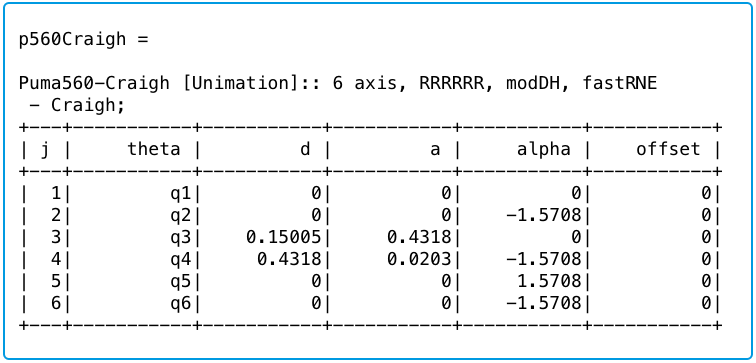

### Animating / Visualizing the chain link connection

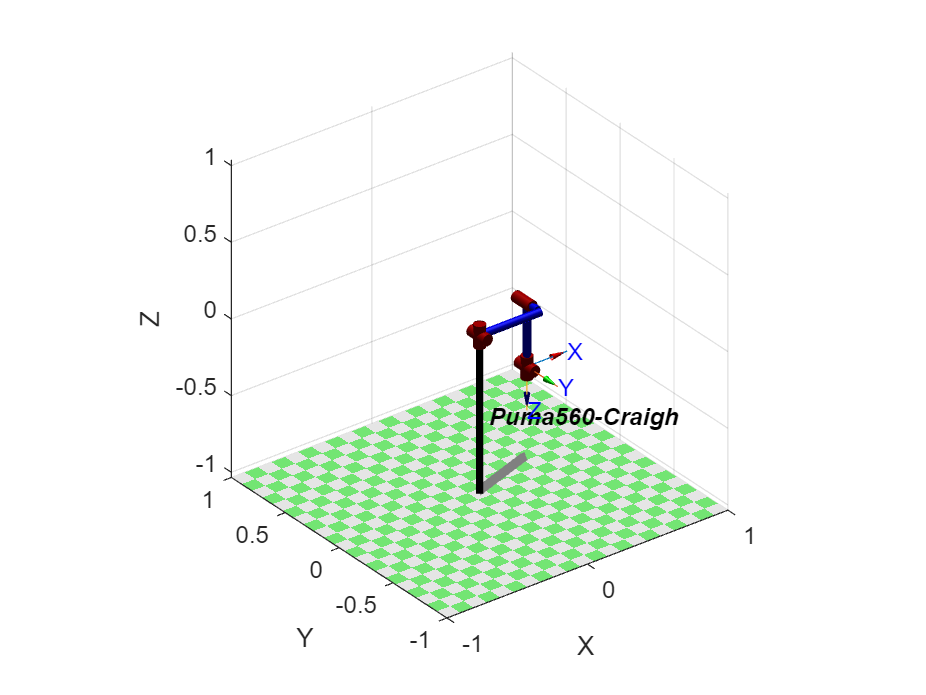

p560Craigh.plot(qz,'zoom',1.5)
hold on

trplot(T_1_0,'length',0.5,'arrow','width', 0.5,'color','black',...
             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})

Unrecognized function or variable 'T_1_0'.

**The Chain**

#### 
$${}_6^0T = {}_1^0T{}_2^1T{}_3^2T{}_4^3T{}_5^4T{}_6^5T$$


#### T_2_0

T_2_0=T_1_0*T_2_1
tranimate(T_1_0,T_2_0,20)

#### T_3_0

T_3_0=T_2_0*T_3_2
tranimate(T_2_0,T_3_0,20)

#### T_4_0

T_4_0=T_3_0*T_4_3
tranimate(T_3_0,T_4_0,20,'length',0.5)

### Fordward Kinematics using RTB 'fkine' 

mdl_puma560_Craigh
T_EE_RTB=p560Craigh.fkine(qz)
p560Craigh.plot(qz,'zoom',1.5)

### Comparing result Hand vs RTB

T_EE_hand_made=T_6_0
T_EE_RTB

Using the RTB puma modified-

Notice it use diferent values for the paramenters

mdl_puma560akb
p560m
T_EE_RTBm=p560m.fkine(qz)

## Standard DH Parameters.

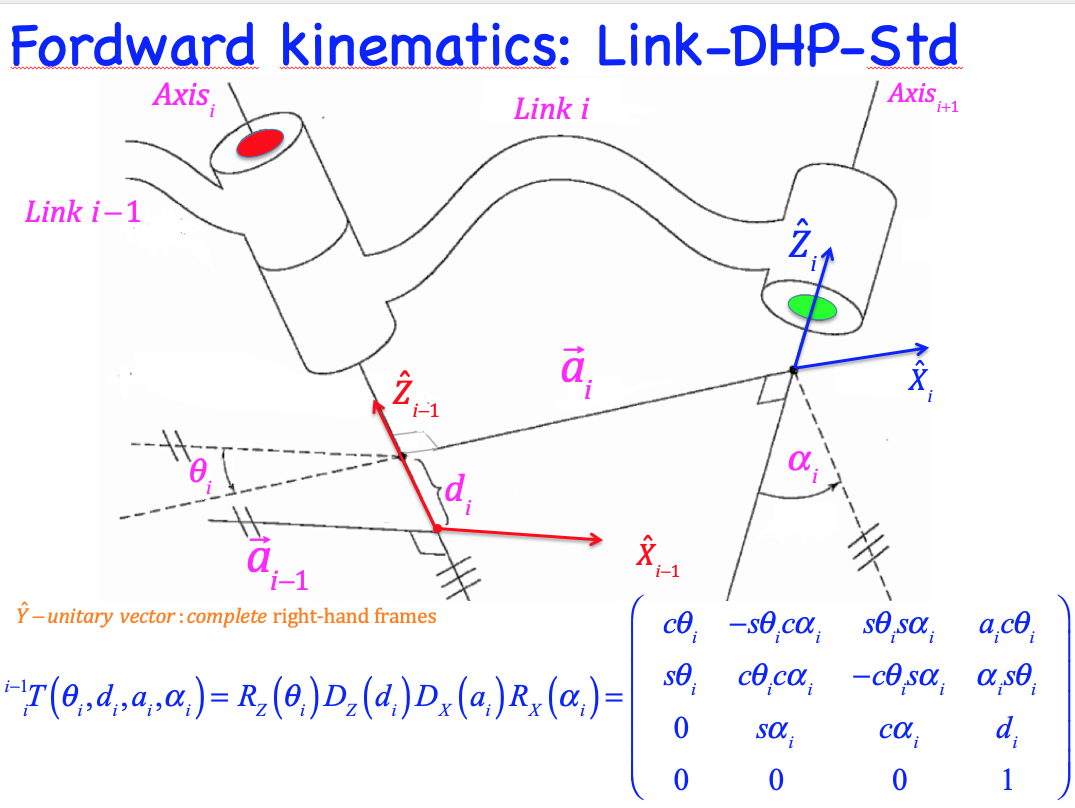

syms alpha_i a_i theta_i  d_i 
T_b_a=trotz(theta_i)*transl(0,0,d_i)*transl(a_i,0,0)*trotx(alpha_i)
T_b_a_mod=trotx(alpha_i_1)*transl(a_i_1,0,0)*trotz(theta_i)*transl(0,0,d_i)

### Standard DH table

The input parameter order into the function is: alpha, a, d, theta.

We test the qz joint vector. all theta = 0

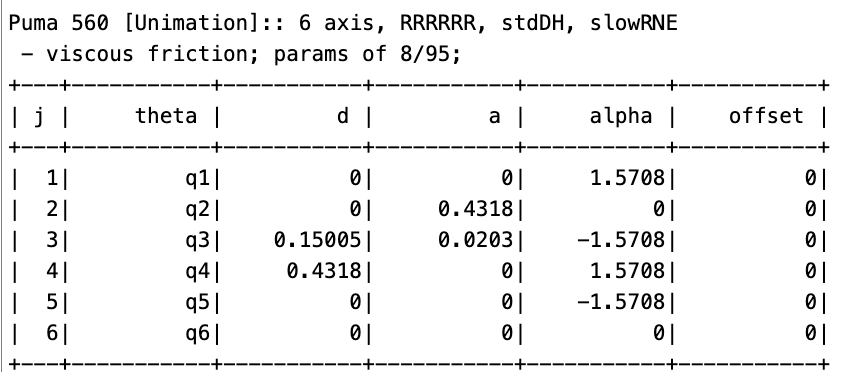

### 'fkine' by hand

The function need (alpha,a,d,theta)

The link chain 

T_1_0=link_A_B_Std(pi/2,0,0,0)
T_2_1=link_A_B_Std(0,0.4318,0,0)
T_3_2=link_A_B_Std(-pi/2,0.0203,0.15005,0)
T_4_3=link_A_B_Std(pi/2,0,0.4318,0)
T_5_4=link_A_B_Std(-pi/2,0,0,0)
T_6_5=link_A_B_Std(0,0,0,0)
T_6_0=T_1_0*T_2_1*T_3_2*T_4_3*T_5_4*T_6_5
T_EE_hand_made=T_6_0
Position=transl(T_EE_hand_made)
Orientation=tr2rpy(T_EE_hand_made)

### Comparing results hand vs RTB

mdl_puma560
T_EE_RTB=p560.fkine(qz)
T_EE_hand_made=T_6_0
p560.plot(qz,'zoom',1.5)
p560.teach

## Wrist orientation

Play with the teach and visit: help tr2rpy RTB function.

q_teach= [1 1 1 1 1 1]*45*pi/180
T_EE_RTB=p560.fkine(q_teach) % Robot pose with all joins at 45 degrees
Wrist_o=tr2rpy(T_EE_RTB.T,'arm')*180/pi

## Functions in the mlx

Put at the end all specific function that clarify the code.

function T_b_a=link_A_B_Md(alpha,a,d,theta)
T_b_a=trotx(alpha)*transl(a,0,0)*trotz(theta)*transl(0,0,d);
end

function T_b_a=link_A_B_Std(alpha,a,d,theta)
T_b_a=trotz(theta)*transl(0,0,d)*transl(a,0,0)*trotx(alpha);
end